# Contents

- Preliminaries

- Network Independant Rates in Distributed Learning

- Robust Asynchronous Stochastic Gradient-Push: Asymptotically Optimal and Network-Independent Performance for Strongly Convex Functions

- Integration

# 1. Preliminaries

### Kullback-Leibler divergence

the Kullback–Leibler divergence is a measure of how one probability distribution is different from a second. It is the expectation of the logarithmic difference between the probabilities P and Q, where the expectation is taken using the probabilities P. The Kullback–Leibler divergence is defined only if for all x, Q(x)=0 implies P(x)=0 (absolute continuity). Whenever P(x) is zero the contribution of the corresponding term is interpreted as zero

Discrete case


$$D_{\textrm{KL}} \left(P\left|\right|Q\right)=\sum_{i=1}^n P\left(i\right)\ln \frac{P\left(i\right)}{Q\left(i\right)}$$


Continous case


$$D_{\textrm{KL}} \left(P\left|\right|Q\right)=\int_{-\infty \;}^{\infty } p\left(x\right)\ln \frac{p\left(x\right)}{q\left(x\right)}\textrm{dx}$$


P = rand(1,10);
P = P/sum(P);
Q = rand(1,10);
Q = Q/sum(Q);
disp(KLDivergence(P,Q))

    0.5423



#### KL-Divergence for Normal Distributions

found at [https://stats.stackexchange.com/questions/7440/kl-divergence-between-two-univariate-gaussians](https://stats.stackexchange.com/questions/7440/kl-divergence-between-two-univariate-gaussians)


$$D_{\textrm{KL}} \left(N\left(\mu_1 ,\sigma_1 \right)\left|\right|N\left(\mu_2 ,\sigma_2 \right)\right)=\log \frac{\sigma_1 }{\sigma_2 }+\frac{\sigma_1^2 +{\left(\mu_1 -\mu_2 \right)}^2 }{2\sigma_2^2 }-\frac{1}{2}$$


sigma1 = 10*rand();
mu1 = 10*(0.5-rand());
sigma2 = 10*rand();
mu2 = 10*(0.5-rand());
disp(KLDivNorm(sigma1,mu1,sigma2,mu2))

    4.9129



# Network Independant Rates in Distributed Learning

## Problem statement

A group of $n$ agents, $V=\left\lbrace 1,2,\ldotp \ldotp \ldotp ,n\right\rbrace$, each observing realizations of independent processes at each time step $k=1,2,\ldotp \ldotp \ldotp$. 

n = 2; % number of agents
k_max = 7; % max time steps

Agent $i$ observes realizations of a sequence of stationary independent, identically distributed random variables $\left\lbrace {S_k }^i \;\right\rbrace$ with unknown distribution $f^i \left(\cdot \right)$. Staking all the random variables at time $k$ generates a single vector ${\mathit{\mathbf{S}}}_{\mathit{\mathbf{k}}}$ distributed as $\mathit{\mathbf{f}}=\prod_{i=1}^n f^i$.

S = zeros(n,k_max); % observed variables
% Case 0 article example with 2 agents
sigma_f = [1 1];
mu_f = [1 2];
% Case 1 setting f_i to be gaussian distributions with sigma = 1 and mu = 0
% sigma_f = ones(n,1);
% mu_f = zeros(n,1);
% Case 2 setting f_i to be gaussian distributions with sigma = 1 and mu = i
% sigma_f = ones(n,1);
% mu_f = (1:n)';
% Case 3 setting f_i to be gaussian distributions with random parameters
% sigma_f = 10*rand(n,1);
% mu_f = 20*(0.5-rand(n,1));
for i = 1:n
    S(i,:) = randn(k_max,1)*sigma_f(i)+mu_f(i);
end

The goal is to determine a consensus about $\theta \in \;\Theta$ that parametrizes the distribution $l^i \left(\cdot \left|\theta \right.\right)$refered as beliefs. There are $m$ sets of parameters $\theta \;$each one with associated with a belief $\mu_k^i$

% since we know that f_i are gaussians, we set l_i as gaussians too 
% the hypothesis are generated randomly in the same range as the original
% with a maximum relative error delta_theta_max
% theta parameters are organized as [sigma_1, sigma_2, ..., sigma_n, mu_1, mu_2, ..., mu_n]
% the beliefs are initialized uniformly
m = 3;
% option 0 article example
sigma_l = [1 1 1;...
           1 1 1];
mu_l = [-0.5, -1.5,  0.0;...
         0.0, -2.5, -1.5];
% option 1 theta generated close to the true values
% delta_theta_max = 0.05;
% sigma_l = sigma_f*ones(1,m);
% sigma_l = sigma_l.*(1+delta_theta_max*2*(0.5-rand(n,m)));
% mu_l = mu_f*ones(1,m);
% mu_l = mu_l.*(1+delta_theta_max*2*(0.5-rand(n,m)));
%theta = [sigma_l, mu_l];
mu = ones(m,n,k_max)/m;

e optimization problem to be solved is:


$$\Theta {\;}^* =\underset{\theta \in \Theta \;}{\textrm{argmax}\;} C\left(\theta \right)$$


Where $C\left(\theta \;\right)$ is called *group confidence *on the hypothesis $\theta \;$and is defined as


$$C\left(\theta \;\right)=-D_{\textrm{KL}} \left(\mathit{\mathbf{f}}\left(\cdot \right)\left|\right|\mathit{\mathbf{l}}\left(\cdot \left|\theta \;\right.\right)\right)$$



$$C\left(\theta \;\right)=-\sum_{i=1}^n D_{\textrm{KL}} \left(f^i \left(\cdot \right)\left|\right|l^i \left(\cdot \left|\theta \;\right.\right)\right)$$


Where $D_{\textrm{KL}} \left(\mathit{\mathbf{f}}\left(\cdot \right)\left|\right|l\left(\cdot \left|\theta \;\right.\right)\right)$ is the Kullback-Leibler divergence between the true distribution $S_k^i$ and the probability distribution $l^i \left(\cdot \left|\theta \right.\right)$ that would have been seen by the agents if the hypothesis $\theta \;$ were correct.

C = zeros(k_max,1);
C(1) = 0;
for i = 1:n
    [~, a_theta] = max(mu(:,i,1));
    C(1) = C(1) - KLDivNorm(sigma_f(i),mu_f(i),sigma_l(i,a_theta),mu_l(i,a_theta));
end

The agents interact in a network modeled as a sequence of directed graphs $\left\lbrace G_k \right\rbrace$ that is B-strongly-connected, i.e. there is an integer $B\ge 1$ such that the graph $\left(V,\underset{i=\textrm{kB}}{\bigcup^{\left(k+1\right)B-1} E_i } \right)$ is connected for all $k\ge 0$.

% % option 0, full connected
% G = ones(n,n,k_max);
% % option 1, random graph (50% of activation chance)
% G = randi([0 1],n,n,k_max);
% for i = 1:n
%     for j = 1:k_max
%         G(i,i,j) = 1;
%     end
% end
% % option 2, cyclic graph (two links each time)
% G = zeros(n,n,k_max);
% for j = 1:k_max
%     G(1+mod(j-1,n),1+mod(j,n),j) = 1;
%     G(1+mod(j,n),1+mod(j+1,n),j) = 1;
%     for i = 1:n
%         G(i,i,j) = 1;
%     end
% end
% % option 3, cyclic graph (single link each time) (B = n)
G = zeros(n,n,k_max);
for j = 1:k_max
    G(1+mod(j-1,n),1+mod(j,n),j) = 1;
    for i = 1:n
        G(i,i,j) = 1;
    end
end

## Belief Update Rule


$$y_0^i =1$$



$$y_{k+1}^i =\sum_{j\in N_k^i }^{\;} \frac{y_k^j }{d_k^j }$$



$$\mu_{k+1}^i \left(\theta \right)=\frac{1}{Z_{k+1}^i }{\left(\prod_{j\in N_k^i } \mu_k^j {\left(\theta \right)}^{\frac{y_k^j }{d_k^j }} l_k^i \left(s_k^i \left|\theta \right.\right)\right)}^{\frac{1}{y_{k+1}^i }}$$



$$Z_{k+1}^i =\sum_{p=1}^m {\left(\prod_{j\in N_k^i } \mu_k^j {\left(\theta \right)}^{\frac{y_k^j }{d_k^j }} l_k^i \left(s_k^i \left|\theta \right.\right)\right)}^{\frac{1}{y_{k+1}^i }}$$


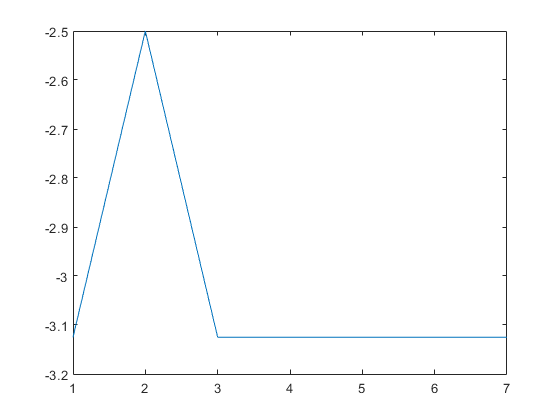

d = zeros(n,k_max);
y = zeros(n,k_max);
l = zeros(m,n,k_max);
z = zeros(1,k_max);
y(:,1) = ones(n,1);
for k = 1:k_max-1
    for i = 1:n
        d(i,k) = sum(G(i,:,k));
    end
    for i = 1:n
        for j = 1:n
            if(G(i,j)==1)
                y(i,k+1) = y(i,k+1) + y(j,k)/d(j,k);
            end
        end
    end
    for i = 1:n
        for p = 1:m
            mu(p,i,k+1) = 1;
            for j = 1:n
                if(G(i,j)==1)
                    l(p,i,k) = normpdf(S(i,k), mu_l(i,p), sigma_l(i,p));
                    mu(p,i,k+1) = mu(p,i,k+1) * (mu(p,j,k)^(y(j,k)/d(j,k))*l(p,i,k)) ^ (1/y(i,k+1));
                end
            end
        end
        z(k+1) = sum(mu(:,i,k+1));
        mu(:,i,k+1) = mu(:,i,k+1)/z(k+1);
    end
    for i = 1:n
        [~, a_theta] = max(mu(:,i,k+1));
        C(k+1) = C(k+1) - KLDivNorm(sigma_f(i),mu_f(i),sigma_l(i,a_theta),mu_l(i,a_theta)); 
    end
end
figure(1)
plot(C)

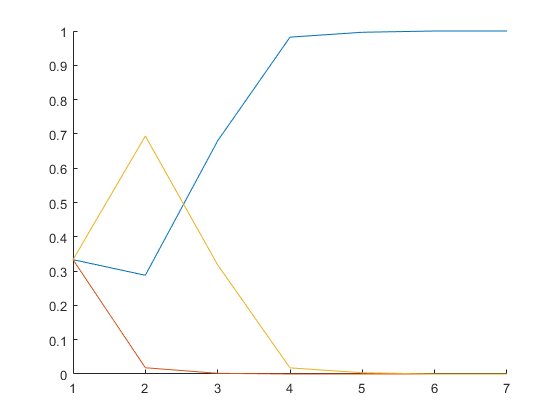

figure(2)
clf
hold on
for p=1:m
    temp = mu(p,1,:);
    plot(temp(:))
end

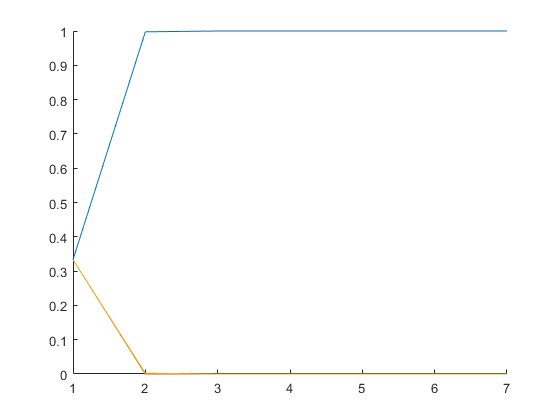

figure(3)
clf
hold on
for p=1:m
    temp = mu(p,2,:);
    plot(temp(:))
end

# Robust Asynchronous Stochastic Gradient-Push: Asymptotically Optimal and Network-Independent Performance for Strongly Convex Functions

We assume there are n agents V = {1, . . . , n}, communicating through a fixed directed graph G = (V, E), where E is the set of directed arcs. We assume G does not have self-loops and is strongly connected.

n = 5;
% arbitrary network topology - ring
G = eye(n);
for i=1:n
    G(1+mod(i-1,n),1+mod(i,n)) = 1;
end
% agents initialization
clear V
for i = 1:n
    V(i) = Agent(i, n, rand, sum(G(:,i))); %#ok<SAGROW>
end

Each node $i$ helds a vector ${\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}}$ (in particular $x_i$ can be a scalar) and the target is to achieve consensus over the average of the initial states.

xm = 0;
for i = 1:n
    xm = xm + V(i).x;
end
xm = xm/n;
disp(xm)

    0.3845



## RASP (Robust Asynchonous Sum-Push)

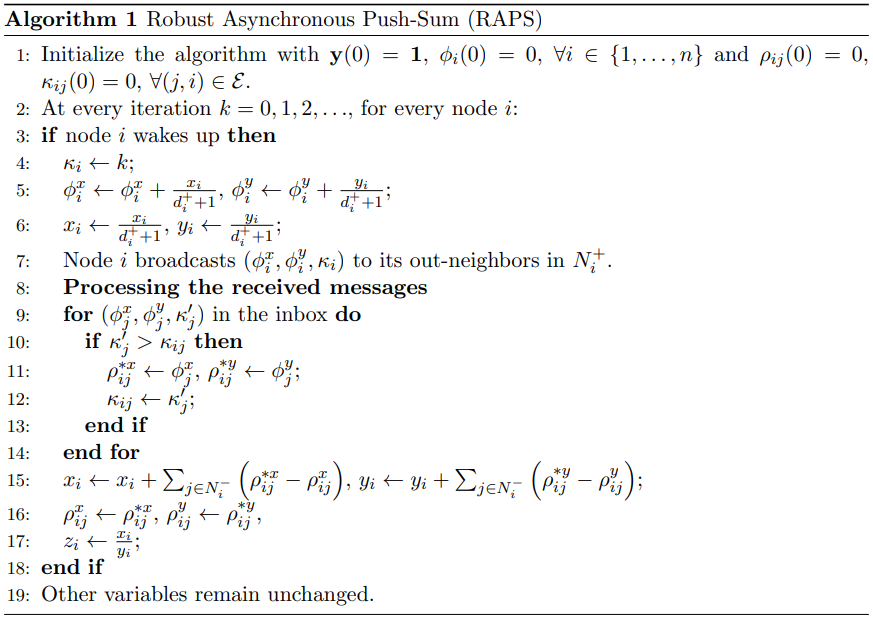

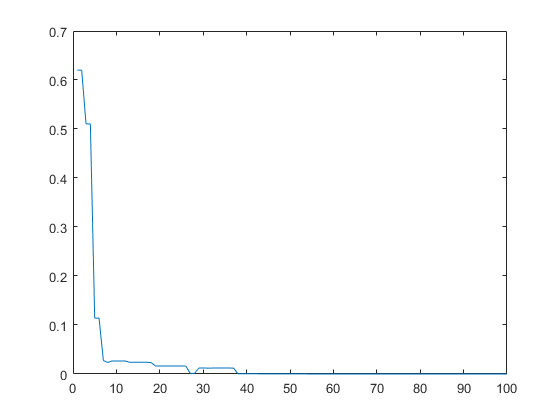

k_max = 100;
wake_prob = 0.25;
loss_prob = 0.10;
C = zeros(k_max,1);
x = zeros(k_max,n);
Y = zeros(k_max,n);
Z = zeros(k_max,n);
PhiX = zeros(k_max,n);
PhiY = zeros(k_max,n);
K = zeros(k_max,n);
for k = 1:k_max
    % actual algorithm
    for i = 1:n
        if(rand<wake_prob)
            V(i).k(i) = k;
            V(i).phix = V(i).phix + V(i).x/(V(i).do+1);
            V(i).phiy = V(i).phiy + V(i).y/(V(i).do+1);
            V(i).x = V(i).x/(V(i).do+1);
            V(i).y = V(i).y/(V(i).do+1);
            for j = 1:n
                if(G(i,j) == 1 && rand > loss_prob)
                    V(j).m_buffer(i,1) = V(i).phix;
                    V(j).m_buffer(i,2) = V(i).phiy;
                    V(j).k(i) = V(i).k(i);
                end
            end
            for j=1:n
                if(G(j,i) == 1)
                    V(i).x = V(i).x + V(i).m_buffer(j,1)-V(i).rhox(j);
                    V(i).y = V(i).y + V(i).m_buffer(j,2)-V(i).rhoy(j);
                    V(i).rhox(j) = V(i).m_buffer(j,1);
                    V(i).rhoy(j) = V(i).m_buffer(j,2);
                    V(i).z = V(i).x/V(i).y;
                end
            end
        end
    end
    % visualization
    for i = 1:n
        C(k) = C(k) + (V(i).z-xm)^2;
        X(k,i) = V(i).x; %#ok<SAGROW> 
        Y(k,i) = V(i).y;
        Z(k,i) = V(i).z;
        PhiX(k,i) = V(i).phix;
        PhiY(k,i) = V(i).phiy;
        K(k,i) = V(i).k(i);
    end
end
figure(1)
plot(C)

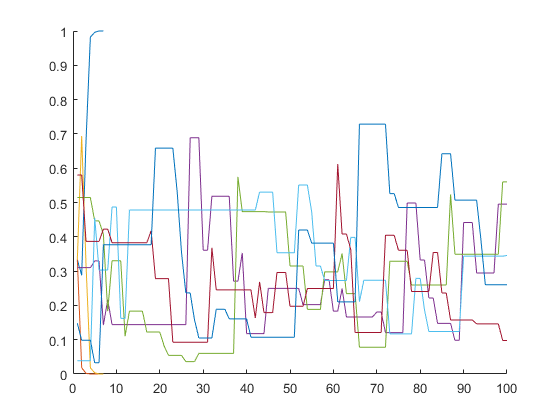

figure(2)
plot(X)

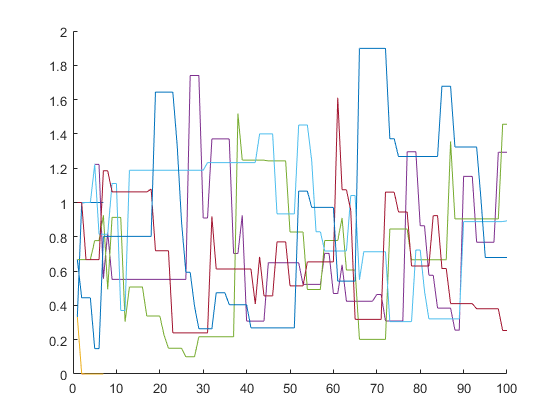

figure(3)
plot(Y)

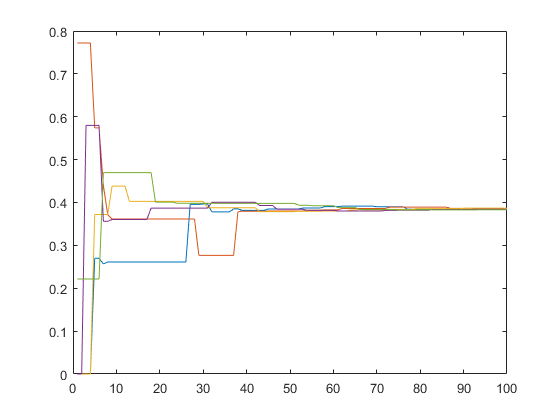

figure(4)
plot(Z)

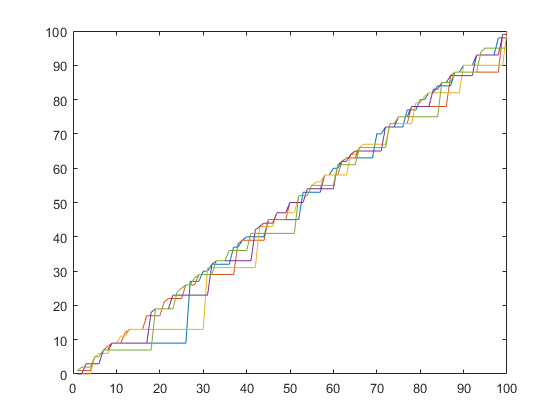

figure(5)
plot(K)

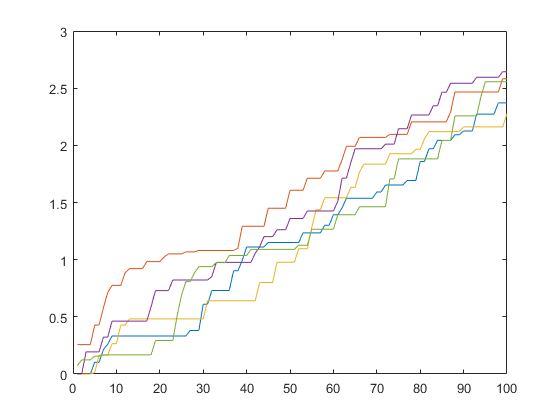

figure(6)
plot(PhiX)

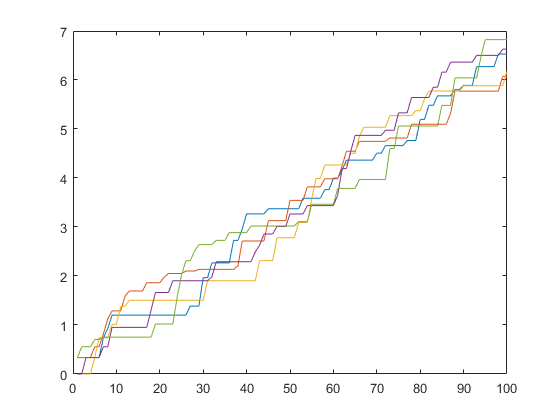

figure(6)
plot(PhiY)

# Integration

## Problem statement

A group of $n$ agents, $V=\left\lbrace 1,2,\ldotp \ldotp \ldotp ,n\right\rbrace$, each observing realizations of independent processes at certain time step $k=1,2,\ldotp \ldotp \ldotp$. 

n = 4; % number of agents
k_max = 200; % max time steps
Lu = 5; % maximum number of consecutive sleeping instants
Lf = 5; % maximum number of consecutive link fails
%% Fixing RNG seed for reprudicibility 
%(wake_prob = 0.9. loss_prob = 0.2, seed = 1, GT = 1 correspond to the Star1)
%(wake_prob = 0.5. loss_prob = 0.1, seed = 6, GT = 1 correspond to the Star2)
%(wake_prob = 0.9. loss_prob = 0.2, seed = 1, GT = 3 correspond to the Path1)
%(wake_prob = 0.5. loss_prob = 0.1, seed = 5, GT = 3 correspond to the Path2)
%(wake_prob = 0.9. loss_prob = 0.2, seed = 1, GT = 5 correspond to the Circle1)
%(wake_prob = 0.5. loss_prob = 0.1, seed = 8, GT = 5 correspond to the Circle2)
wake_prob = 0.5;
loss_prob = 0.1;
rng(1);
GT = 5;

Agent $i$ observes realizations of a sequence of stationary independent, identically distributed random variables $\left\lbrace {S_k }^i \;\right\rbrace$ with unknown distribution $f^i \left(\cdot \right)$. Staking all the random variables at time $k$ generates a single vector ${\mathit{\mathbf{S}}}_{\mathit{\mathbf{k}}}$ distributed as $\mathit{\mathbf{f}}=\prod_{i=1}^n f^i$.

S = zeros(n,k_max); % observed variables
% Case 0 fixed values
sigma_f = ones(n,1);
mu_f = [1 2 3 4]';
% Case 1 setting f_i to be gaussian distributions with sigma = 1 and mu = 0
% sigma_f = ones(n,1);
% mu_f = zeros(n,1);
% Case 2 setting f_i to be gaussian distributions with sigma = 1 and mu = i
% sigma_f = ones(n,1);
% mu_f = (1:n)';
% Case 3 setting f_i to be gaussian distributions with random parameters
% sigma_f = 10*rand(n,1);
% mu_f = 20*(0.5-rand(n,1));
for i = 1:n
    S(i,:) = randn(k_max,1)*sigma_f(i)+mu_f(i);
end

The goal is to determine a consensus about $\theta \in \;\Theta$ that parametrizes the distribution $l^i \left(\cdot \left|\theta \;\right.\right)$refered as beliefs. There are $m$ sets of parameters $\theta \;$each one with associated with a belief $\mu_k^i$

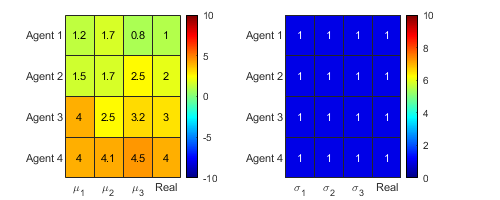

% since we know that f_i are gaussians, we set l_i as gaussians too 
% the hypothesis are generated randomly in the same range as the original
% with a maximum relative error delta_theta_max
% theta parameters are organized as [sigma_1, sigma_2, ..., sigma_n, mu_1, mu_2, ..., mu_n]
% the beliefs are initialized uniformly
m = 3;
% option 0 fixed values
sigma_l = ones(n,m);
mu_l = [ 1.2, 1.7, 0.8;...
         1.5, 1.7, 2.5;...
         4.0, 2.5, 3.2;...
         4.0, 4.1, 4.5];
% option 1 theta generated close to the true values
% delta_theta_max = 0.25;
% sigma_l = repmat(sigma_f,1,m);
% sigma_l = sigma_l.*(1+delta_theta_max*2*(0.5-rand(n,m)));
% mu_l = repmat(mu_f,1,m);
% mu_l = mu_l.*(1+delta_theta_max*2*(0.5-rand(n,m)));
theta = [sigma_l, mu_l];
f = figure();
set(f, 'Position', [0 0 500 200])
subplot(1,2,1)
xvalues = ["\mu_1", "\mu_2", "\mu_3", "Real"];
yvalues = ["Agent 1", "Agent 2", "Agent 3", "Agent 4"];
heatmap(xvalues, yvalues, [mu_l mu_f], 'Colormap', jet, 'ColorLimits', [-10,10])
subplot(1,2,2)
xvalues = ["\sigma_1", "\sigma_2", "\sigma_3", "Real"];
yvalues = ["Agent 1", "Agent 2", "Agent 3", "Agent 4"];
heatmap(xvalues, yvalues, [sigma_l sigma_f], 'Colormap', jet, 'ColorLimits', [0,10])

e optimization problem to be solved is:


$$\Theta {\;}^* =\underset{\theta \in \Theta \;}{\textrm{argmax}\;} C\left(\theta \;\right)$$


Where $C\left(\theta \;\right)$ is called *group confidence *on the hypothesis $\theta \;$and is defined as


$$C\left(\theta \;\right)=-D_{\textrm{KL}} \left(\mathit{\mathbf{f}}\left(\cdot \right)\left|\right|\mathit{\mathbf{l}}\left(\cdot \left|\theta \;\right.\right)\right)$$



$$C\left(\theta \;\right)=-\sum_{i=1}^n D_{\textrm{KL}} \left(f^i \left(\cdot \right)\left|\right|l^i \left(\cdot \left|\theta \;\right.\right)\right)$$


Where $D_{\textrm{KL}} \left(\mathit{\mathbf{f}}\left(\cdot \right)\left|\right|l\left(\cdot \left|\theta \;\right.\right)\right)$ is the Kullback-Leibler divergence between the true distribution $S_k^i$ and the probability distribution $l^i \left(\cdot \left|\theta \right.\right)$ that would have been seen by the agents if the hypothesis $\theta \;$ were correct.

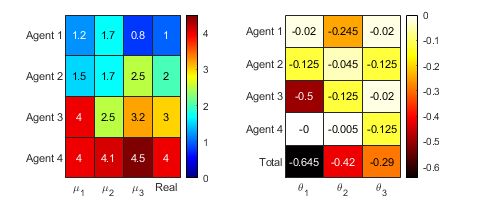

C_table = zeros(n+1,m);
for i = 1:n
    for j=1:m
        C_table(i,j) = - KLDivNorm(sigma_f(i),mu_f(i),sigma_l(i,j),mu_l(i,j));
        C_table(n+1,j) = C_table(n+1,j)+ C_table(i,j);
    end
    
end
f = figure();
set(f, 'Position', [0 0 500 200])
subplot(1,2,1)
xvalues = ["\mu_1", "\mu_2", "\mu_3", "Real"];
yvalues = ["Agent 1", "Agent 2", "Agent 3", "Agent 4"];
heatmap(xvalues, yvalues, [mu_l mu_f], 'Colormap', jet, 'ColorLimits', [0,4.5])
subplot(1,2,2)
xvalues = ["\theta_1", "\theta_2", "\theta_3"];
yvalues = ["Agent 1", "Agent 2", "Agent 3", "Agent 4", "Total",];
heatmap(xvalues, yvalues, C_table, 'Colormap', hot)

The agents interact in a network modeled as a sequence of directed graphs $\left\lbrace G_k \right\rbrace$ that is B-strongly-connected, i.e. there is an integer $B\ge 1$ such that the graph $\left(V,\underset{i=\textrm{kB}}{\bigcup^{\left(k+1\right)B-1} } E_i \right)$ is connected for all $k\ge 0$.

switch GT
    case 1 % star graph (everyone talks to node 1)
        G = zeros(n,n,k_max);
        for i = 1:n
            for k = 1:k_max
                G(i,i,k) = 1;
                G(i,1,k) = 1;
                G(1,i,k) = 1;
            end
        end
    case 2 % random non-directed graph each time 1/n probability of connection
        G = zeros(n,n,k_max);
        for i = 1:n
            for k = 1:k_max
                for j=1:n
                    if(rand()<1/n)
                        G(i,j,k) = 1*(0.5*rand()<1/n);
                        G(j,i,k) = G(i,j,k);
                    end
                end
                G(i,i,k) = 1;
            end
        end
    case 3 % open non-directed path
        G = zeros(n,n,k_max);
        for k = 1:k_max
            G(:,:,k) = eye(n);
            for i = 1:n-1
                G(i,i+1,k) = 1;
            end
            for i = n:-1:2
                G(i,i-1,k) = 1;
            end
        end
    case 4 % random graph each time 1/n probability of connection
        G = zeros(n,n,k_max);
        for i = 1:n
            for k = 1:k_max
                for j=1:n
                    G(i,j,k) = 1*(rand()<1/n);
                    G(j,i,k) = 1*(rand()<1/n);
                end
                G(i,i,k) = 1;
            end
        end
    case 5 % circular graph (undirected)
        G = zeros(n,n,k_max);
        for k = 1:k_max
            G(:,:,k) = eye(n);
            for i=1:n-1
                G(i,i+1,k) = 1;
                G(i+1,i,k) = 1;
            end
            G(n,1,k) = 1;
            G(1,n,k) = 1;
        end
    case 6 % circular graph (directed)
        G = zeros(n,n,k_max);
        for k = 1:k_max
            G(:,:,k) = eye(n);
            for i=1:n-1
                G(i,i+1,k) = 1;
            end
            G(n,1) = 1;
        end
    case 7 % cyclic graph (two links each time)
        G = zeros(n,n,k_max);
        for j = 1:k_max
            G(1+mod(j-1,n),1+mod(j,n),j) = 1;
            G(1+mod(j,n),1+mod(j+1,n),j) = 1;
            for i = 1:n
                G(i,i,j) = 1;
            end
        end
    case 8 % cyclic graph (single link each time) (B = n)
        G = zeros(n,n,k_max);
        for j = 1:k_max
            G(1+mod(j-1,n),1+mod(j,n),j) = 1;
            for i = 1:n
                G(i,i,j) = 1;
            end
        end
    otherwise % full connected
        G = ones(n,n,k_max);
end

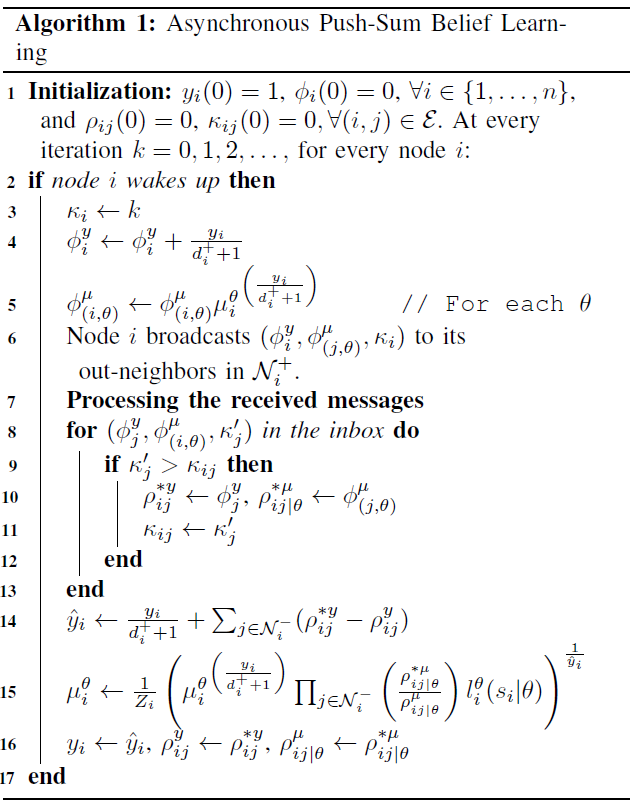

wake_counter = 0;
loss_counter = 0;
% agents initialization
clear V
for i = 1:n
    V(i) = Agent3(i, n, mu_l(i,:), sigma_l(i,:), theta, m, sum(G(:,i,1))-1); %#ok<SAGROW>
end
% visualization variables
mu_v = ones(n,m,k_max+1)/m;
y_v = zeros(n,k_max+1);
od_v = zeros(n,k_max+1);
k_v = zeros(n,n,k_max+1);
phi_y_v = zeros(n,k_max+1);
phi_mu_v = zeros(n,m,k_max+1);
G_v = G;
wake_v = zeros(n,k_max+1);
C = zeros(k_max+1,1);
Convergence = zeros(n,1);
stop = false;
mu_min = 0.001;
% iterative loop
for k = 1:k_max
    % actual algorithm
    for i = 1:n
        if (rand < wake_prob || wake_counter >= Lu)
            wake_counter = 0;
            wake_v(i,k+1) = 1;
            od = sum(G(:,i,k))-1; % output degree
            V(i) = V(i).selfUpdate(k, S(i,k), od);
            for j = 1:n % messages broadcast
                if(G(i,j,k) == 1 && i~=j)
                    if(rand > loss_prob || loss_counter >= Lf)
                        V(j).y_buff(i) = V(i).phi_y;
                        V(j).mu_buff(i,:) = V(i).phi_mu(:);
                        V(j).k_buff(i) = k;
                        loss_counter = 0;
                    else
                        loss_counter = loss_counter + 1;
                        G_v(i,j,k) = 0;
                    end
                end
            end
            % Beliefs Updating
            if(sum(V(i).mu>=1-mu_min)~=0 && Convergence(i)~=1) % Check agent convergence
                disp(['el agente ' num2str(i) ' convergió en la iteración ' num2str(k)])
                Convergence(i) = 1;
            % elseif(Convergence(i)==0)
            else
                if(sum(V(i).mu<=mu_min)~=0 && Convergence(i)~=1)  % Check and repairs discarted hypothesis
%                     disp(['descarte detectado en el agente ' num2str(i)...
%                           ' en la iteración ' num2str(k) ' :' num2str(V(i).mu')])
                    V(i).mu((V(i).mu==0)) = mu_min;
                    V(i).mu = V(i).mu/sum(V(i).mu);
%                     disp(['reparación :' num2str(V(i).mu')])
                end
                if(sum(isnan(V(i).mu))~=0)  % Check for NaN hypothesis
                    disp(['NaN detectado en el agente ' num2str(i) ' en la iteración ' num2str(k)])
                    stop = true;
                    break
                end
                V(i) = V(i).processMessages();
            end
        else
            wake_counter = wake_counter + 1;
            G_v(i,:,k) = zeros(1,n);
        end
    end
    % visualization
    for i = 1:n
        for p = 1:m
            mu_v(i,p,k+1) = V(i).mu(p);
        end
        y_v(i,k+1) = V(i).y;
        od_v(i,k+1) = V(i).od;
        for j = 1:n
            k_v(i,j,k+1) = V(i).k(j);
        end
        phi_y_v(i,k+1) = V(i).phi_y;
        for p = 1:m
            phi_mu_v(i,p,k+1) = V(i).phi_mu(p);
        end
        [~, a_theta] = max(V(i).mu(:));
        C(k+1) = C(k+1) - KLDivNorm(sigma_f(i),mu_f(i),sigma_l(i,a_theta),mu_l(i,a_theta));
    end
    % Stop condition
    if(sum(Convergence) == n || stop)
        mu_v = mu_v(:,:,1:k+1);
        y_v = y_v(:,1:k+1);
        od_v = od_v(:,1:k+1);
        k_v = k_v(:,:,1:k+1);
        phi_y_v = phi_y_v(:,1:k+1);
        phi_mu_v = phi_mu_v(:,:,1:k+1);
        wake_v = wake_v(:,1:k+1);
        C = C(2:k+1);
        G = G(:,:,1:k+1);
        G_v = G_v(:,:,1:k+1);
        if(stop)
            disp(['Falló por detección de NaN tras ' num2str(k) ' iteraciones'])
        else
            disp(['Todos los agentes convergieron en ' num2str(k) ' iteraciones'])
        end
        break
    end
end

el agente 2 convergió en la iteración 36
el agente 1 convergió en la iteración 75
el agente 4 convergió en la iteración 110
el agente 3 convergió en la iteración 117


Todos los agentes convergieron en 117 iteraciones


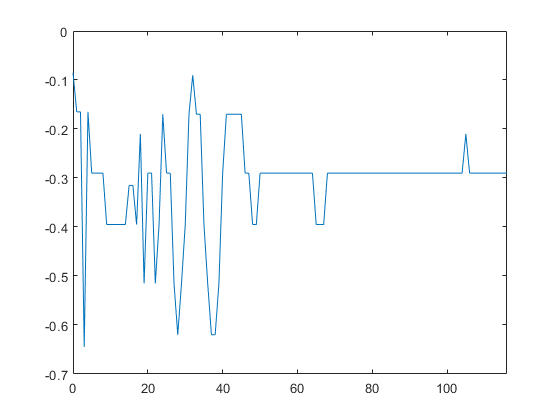

figure(1)
clf
plot(0:length(C)-1,C)
xlim([0,k-1])

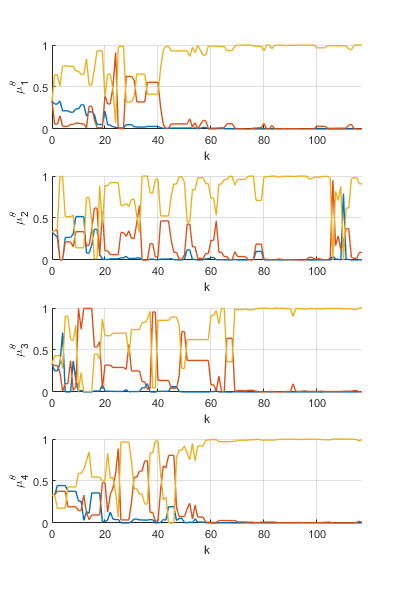

f2 = figure(2);
clf
set(f2, 'Position', [0 0 400 600])
for i = 1:n
    subplot(n,1,i)
    %title(['Beliefs \mu_' num2str(i) '^\theta'])
    hold on
    grid on
    for j=1:p
        pmu = mu_v(i,j,:);
        plot(0:k,pmu(:),'LineWidth',1)
        xlim([0,k])
        xlabel('k')
        ylabel(['\mu_' num2str(i) '^\theta'])
    end
    %legend({'a','b','c'})
end

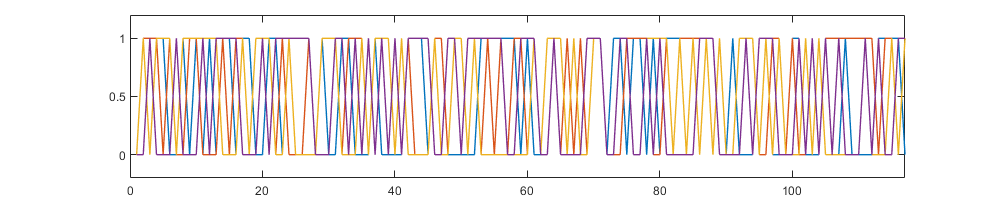

f3 = figure(3);
clf
set(f3, 'Position', [0 0 1000 200])
plot(wake_v','LineWidth',1)
xlim([0,k])
ylim([-0.2,1.2])